# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
 file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
% file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
% file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 18.44 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.20 MSps
	 Ramp End Time: 		 26.56 us
	 Chirp Tx Bandwidth: 		 26.56 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 20.00 us
	 Chirp Cycle Time: 		 45.00 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 11.52 ms


%log detection first, then log all the data about it
simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.67 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 1110.34 m/s
	 Velocity Resolution 		 8.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 28.80 MHz
	 Downsampling factor 		 9
	 Sweep time 			 26.56 us
	 Samples per chirp 		 1296.00 


## Initialize the Target

simulator.load_target_realistic(3,-5);

## Run the simulation

%specify the number of frames and chirps to compute
frames_to_compute = 20;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%run the simulation (without an attacker for now)
simulator.run_simulation_no_attack(frames_to_compute,true);

## Results

% determine if an object has been detected in each frame
detected = performance_functions.detection(frames_to_compute, simulator.Victim.Radar_Signal_Processor.range_estimates)

detected =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   

% report the range estimates
estimated_ranges = simulator.Victim.Radar_Signal_Processor.range_estimates

estimated_ranges =     2.9954       NaN       NaN       NaN       NaN
    2.7142       NaN       NaN       NaN       NaN
    2.5410       NaN       NaN       NaN       NaN
    2.2462       NaN       NaN       NaN       NaN
    2.0506       NaN       NaN       NaN       NaN
    1.8349       NaN       NaN       NaN       NaN
    1.5389       NaN       NaN       NaN       NaN
    1.4240       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


% compute the actual range per frame
actual_ranges = performance_functions.actual_ranges(frames_to_compute, simulator.Victim.FramePeriodicity_ms*.001, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s, simulator.SimulatedTarget.position_m, simulator.Victim.position_m)

actual_ranges =     3.0000    2.7666    2.5332    2.2998    2.0663    1.8329    1.5995    1.3661    1.1327    0.8993    0.6658    0.4324    0.1990    0.0344    0.2678    0.5012    0.7347    0.9681    1.2015    1.4349


% compute the percent error of the range estimate for each frame
percent_error_ranges = performance_functions.range_percent_error(actual_ranges, estimated_ranges)

percent_error_ranges =     0.0046
    0.0524
    0.0078
    0.0535
    0.0157
    0.0020
    0.0606
    0.0579
         0
         0


% report the velocity estimates
estimated_velocities = simulator.Victim.Radar_Signal_Processor.velocity_estimates

estimated_velocities =     6.9523       NaN       NaN       NaN       NaN
    6.9914       NaN       NaN       NaN       NaN
    6.9869       NaN       NaN       NaN       NaN
    6.9633       NaN       NaN       NaN       NaN
    6.9939       NaN       NaN       NaN       NaN
    6.9512       NaN       NaN       NaN       NaN
    6.9926       NaN       NaN       NaN       NaN
    7.0013       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


% compute the actual velocity per frame
actual_velocities = performance_functions.actual_velocities(frames_to_compute, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s)

actual_velocities =      7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7


% compute the velocity percent error per frame
percent_error_velocities = performance_functions.velocity_percent_error(estimated_velocities, actual_velocities)

percent_error_velocities =    -0.0477
   -0.0086
   -0.0131
   -0.0367
   -0.0061
   -0.0488
   -0.0074
    0.0013
         0
         0


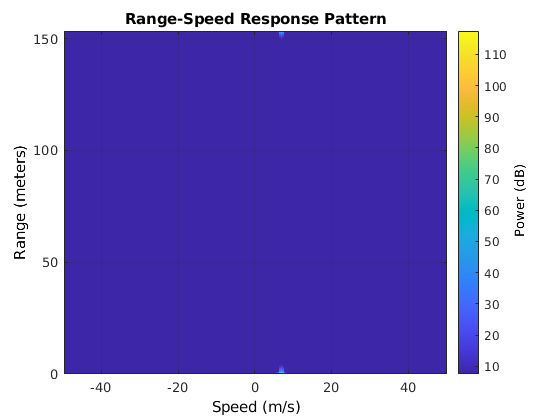

%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

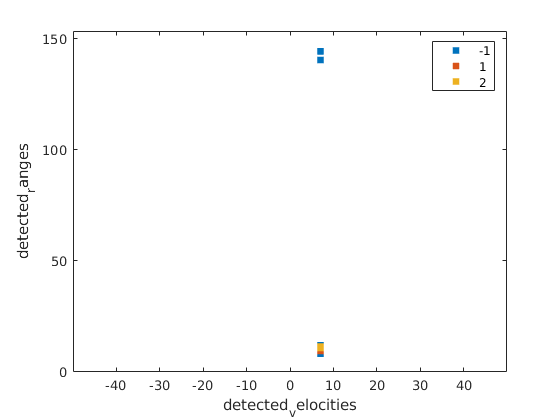

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end